# 3/21/2016 - DJC. This is an exploratory Beta-triggered stimulation script in preparation for the site visit and manuscript preparation 

Code to calculate distances between electrodes in grid

Starting with 0b5a2e 

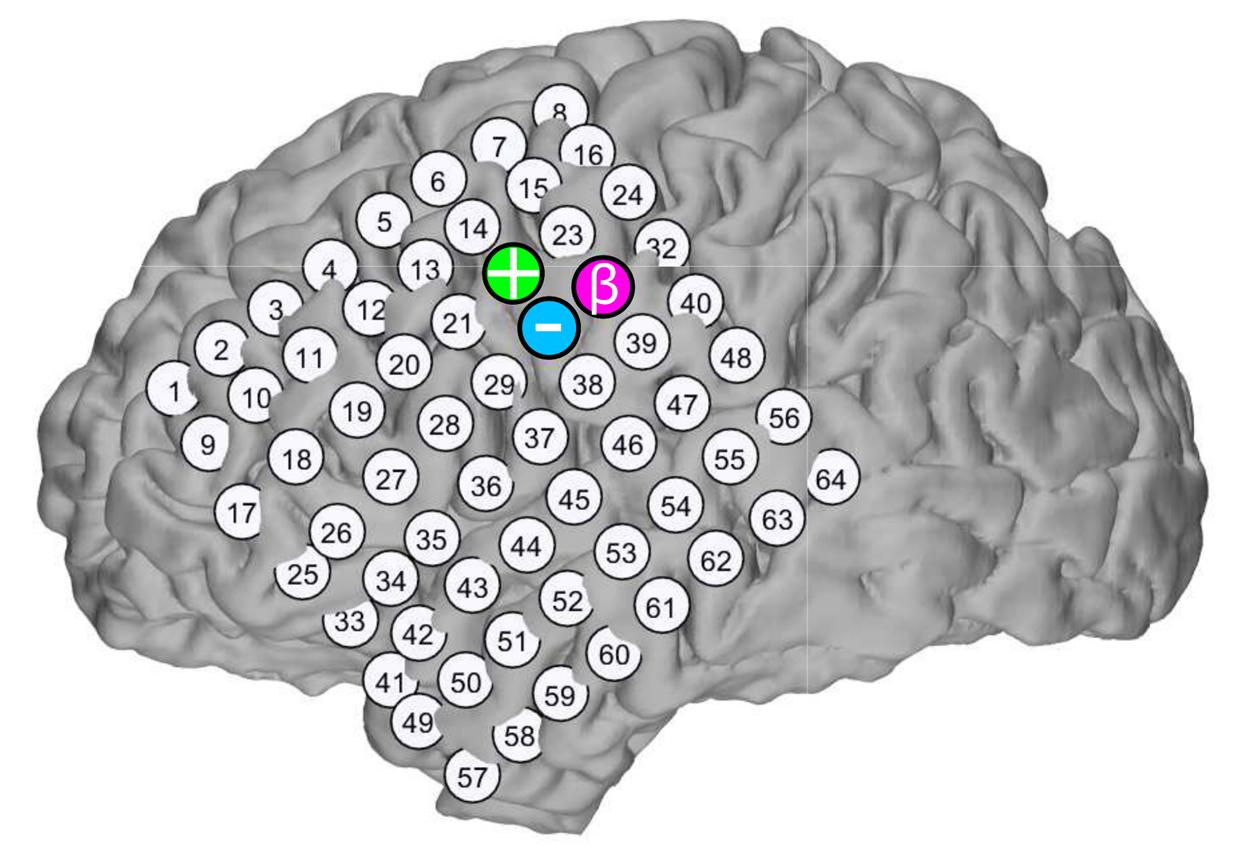

% sid
sid = '0b5a2e'

sid = 0b5a2e


% load montage 
Montage.Montage = 64;
Montage.MontageTokenized = {'Grid(1:64)'};
Montage.MontageString = Montage.MontageTokenized{:};
Montage.MontageTrodes = zeros(64, 3);
Montage.BadChannels = [];
Montage.Default = true;

% get electrode locations
locs = trodeLocsFromMontage(sid, Montage, false);
Grid = locs;

% scatter plot of electrode locations
figure
c = linspace(1,10,size(locs,1));

% take labeling from plot dots direct
h = scatter3(locs(:,1),locs(:,2),locs(:,3),[100],c,'filled')

h =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
           SizeData: 100
          LineWidth: 0.5000
              XData: [1x64 double]
              YData: [1x64 double]
              ZData: [1x64 double]
              CData: [1x64 double]

  Show all properties


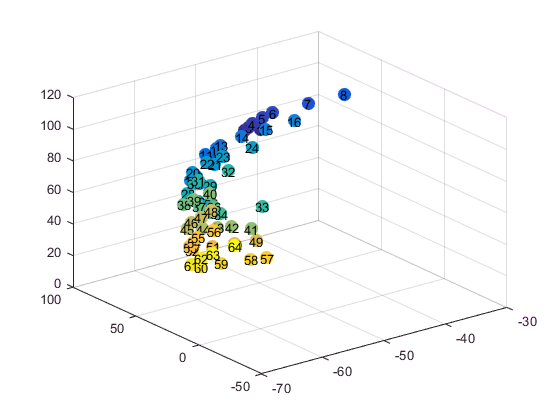



gridSize = 64;

trodeLabels = [1:gridSize];
for chan = 1:gridSize
    txt = num2str(trodeLabels(chan));
t = text(locs(chan,1),locs(chan,2),locs(chan,3),txt,'FontSize',10,'HorizontalAlignment','center','VerticalAlignment','middle');
set(t,'clipping','on');
end


% plot cortex too
figure
PlotCortex(sid,'l')
hold on
h = scatter3(locs(:,1),locs(:,2),locs(:,3),100,c,'filled')

h =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
           SizeData: 100
          LineWidth: 0.5000
              XData: [1x64 double]
              YData: [1x64 double]
              ZData: [1x64 double]
              CData: [1x64 double]

  Show all properties


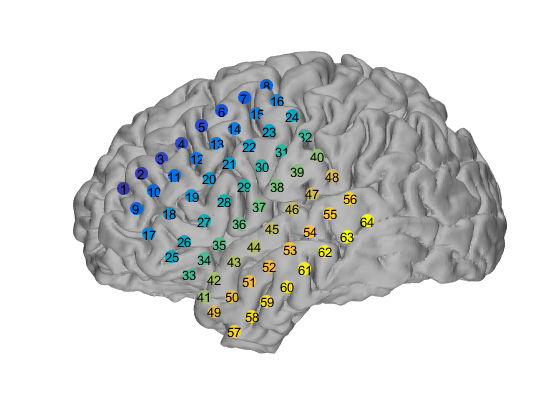

for chan = 1:gridSize
    txt = num2str(trodeLabels(chan));
t = text(locs(chan,1),locs(chan,2),locs(chan,3),txt,'FontSize',10,'HorizontalAlignment','center','VerticalAlignment','middle');
set(t,'clipping','on');
end

Now it's time to calculate the distances between objects

distances = matrixDist(locs);


calculate the distances from the stimulation sites, from the beta-triggered site?

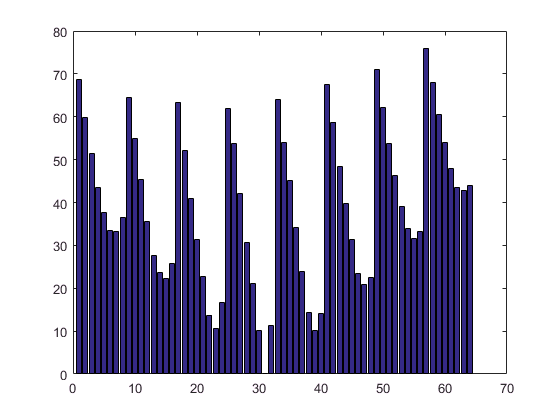

beta = 31;
stim1 = 22;
stim2 = 30;

betaDist = channelExtract(distances,beta);
stim1Dist = channelExtract(distances,stim1);
stim2Dist = channelExtract(distances,stim2);

figure
bar(betaDist)

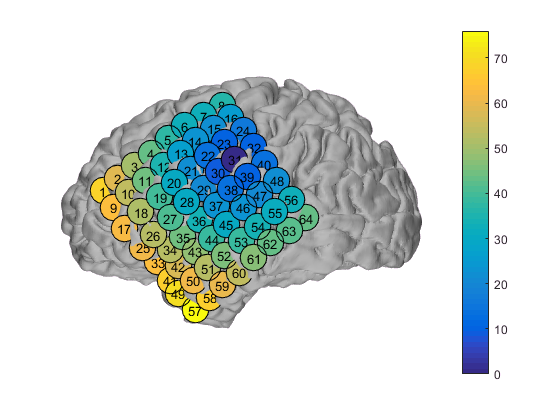


% plot distances

weights = betaDist;
clims = [min(betaDist) max(betaDist)];
figure
PlotDotsDirect(sid,locs,weights,determineHemisphereOfCoverage(sid), clims, 20,'parula', 1:gridSize, true);
% very often, after plotting the brain and dots, I add a colorbar for
% reference as to what the dot colors mean
colorbar;

Load in the important data 

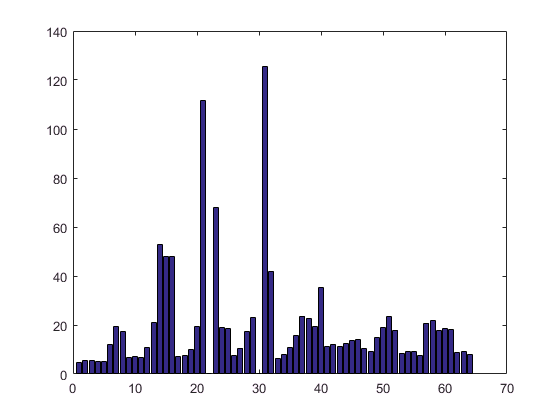

SUB_DIR = fullfile(myGetenv('subject_dir'));
OUTPUT_DIR = fullfile(myGetenv('OUTPUT_DIR'));
load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','RaoLabMeeting2-26-2016','0b5a2eepSTATSsig'))
load tTemp.mat



chans = [1:64];
stims = [22 30];
logChans = chans;
logChans(stims) = 0;
logChans = logical(logChans);

for chan = chans
   if (chan~=stims)
    type1 = cell2mat([CCEPbyNumStim{chan}{1}{1:3}]);
    type2 = cell2mat([CCEPbyNumStim{chan}{2}{1:3}]);
    BigAveResp(chan) = (type1(14)+type2(14))/2;
    latencyResp(chan) = (type1(15)+type2(15))/2;
   end
end

figure
bar(BigAveResp)

Do a scatter plot of response vs. distance - > 5 stims

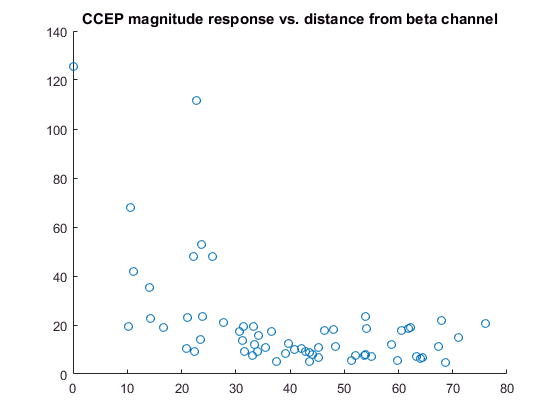

figure
scatter(betaDist(logChans),BigAveResp(logChans))
title('CCEP magnitude response vs. distance from beta channel')

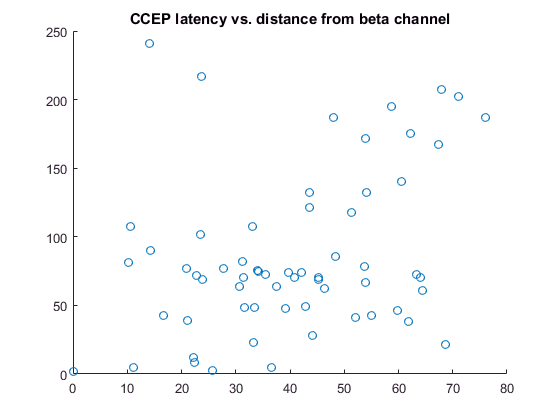


figure
scatter(betaDist(logChans),latencyResp(logChans))
title('CCEP latency vs. distance from beta channel')

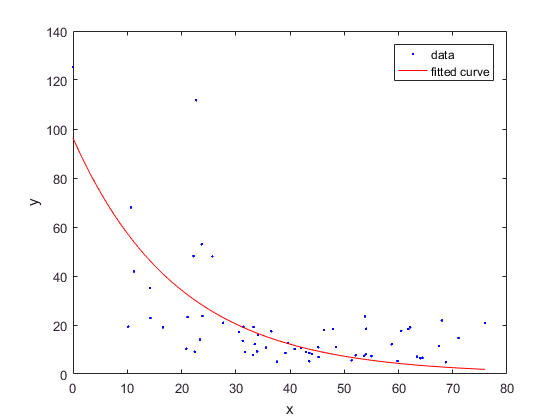


figure
[f,gof] = fit(betaDist(logChans)',BigAveResp(logChans)','exp1');
plot(f,betaDist(logChans),BigAveResp(logChans))

gof

gof =            sse: 1.5884e+04
       rsquare: 0.4636
           dfe: 60
    adjrsquare: 0.4546
          rmse: 16.2706


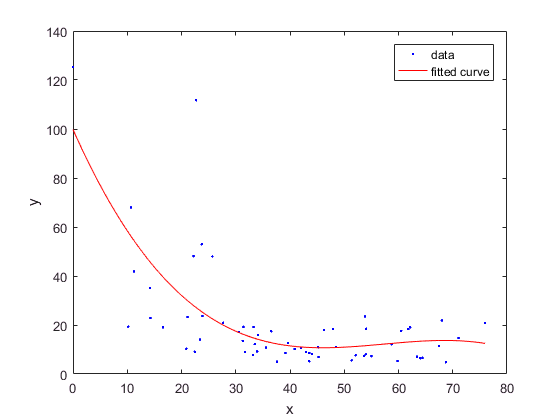


figure
[f,gof] = fit(betaDist(logChans)',BigAveResp(logChans)','poly3');
plot(f,betaDist(logChans),BigAveResp(logChans))

gof

gof =            sse: 1.4589e+04
       rsquare: 0.5073
           dfe: 58
    adjrsquare: 0.4818
          rmse: 15.8600


Do a scatter plot of response vs. distance -  3,4 stims

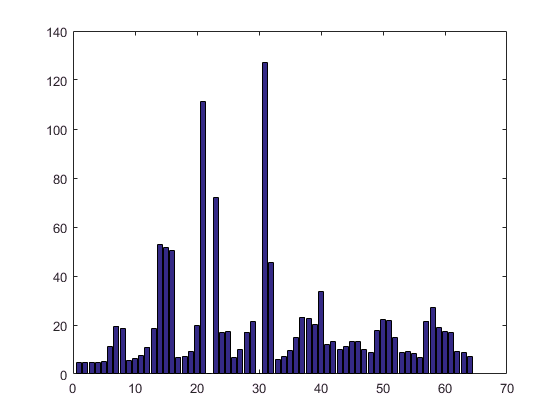

for chan = chans
   if (chan~=stims)
    type1 = cell2mat([CCEPbyNumStim{chan}{1}{1:3}]);
    type2 = cell2mat([CCEPbyNumStim{chan}{2}{1:3}]);
    BigAveResp(chan) = (type1(8)+type2(8))/2;
    latencyResp(chan) = (type1(9)+type2(9))/2;

   end
end


figure
bar(BigAveResp)

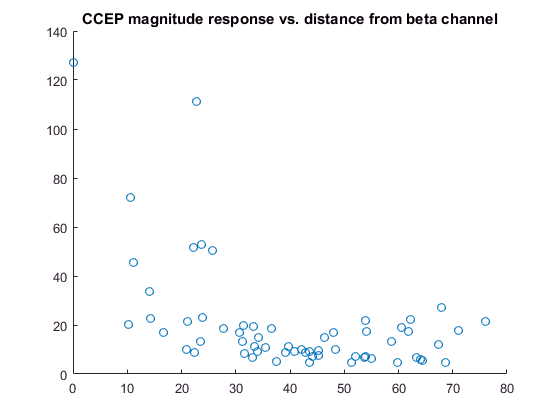


figure
scatter(betaDist(logChans),BigAveResp(logChans))
title('CCEP magnitude response vs. distance from beta channel')

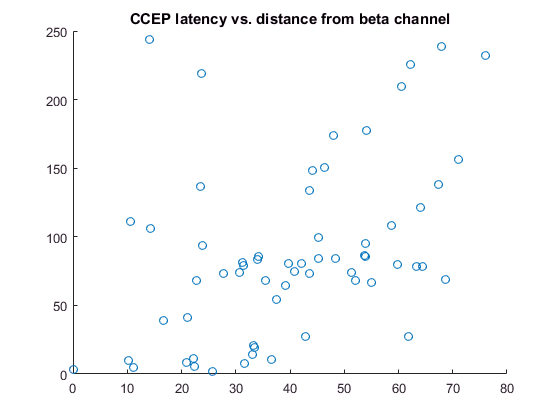


figure
scatter(betaDist(logChans),latencyResp(logChans))
title('CCEP latency vs. distance from beta channel')


figure
[f,gof] = fit(betaDist(logChans)',BigAveResp(logChans)','exp1','Robust','LAR')

f =      General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       60.51  (54.73, 66.28)
       b =    -0.04131  (-0.04543, -0.03719)

gof =            sse: 1.0144e+03
       rsquare: 0.9674
           dfe: 60
    adjrsquare: 0.9669
          rmse: 4.1117


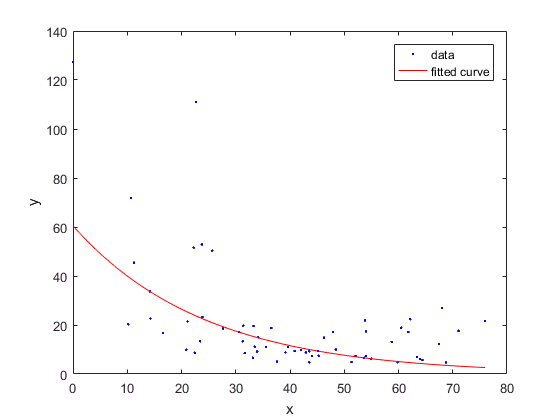

plot(f,betaDist(logChans),BigAveResp(logChans))

gof

gof =            sse: 1.0144e+03
       rsquare: 0.9674
           dfe: 60
    adjrsquare: 0.9669
          rmse: 4.1117


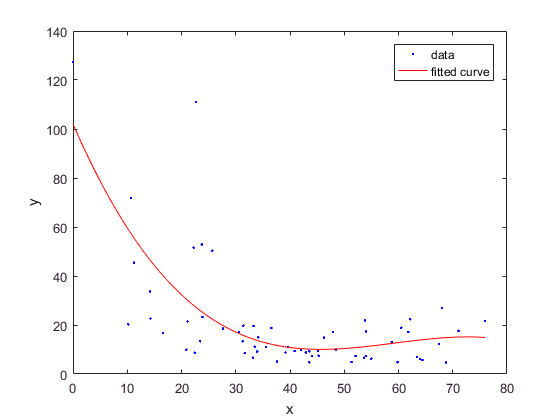


figure
[f,gof] = fit(betaDist(logChans)',BigAveResp(logChans)','poly3');
plot(f,betaDist(logChans),BigAveResp(logChans))

gof

gof =            sse: 1.5218e+04
       rsquare: 0.5113
           dfe: 58
    adjrsquare: 0.4860
          rmse: 16.1982


Do a scatter plot of response vs. distance - 1,2 stims 

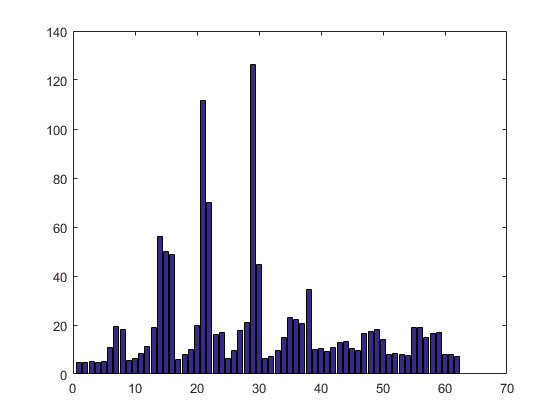


for chan = chans
   if (chan~=stims)
    type1 = cell2mat([CCEPbyNumStim{chan}{1}{1:3}]);
    type2 = cell2mat([CCEPbyNumStim{chan}{2}{1:3}]);
    BigAveResp(chan) = (type1(2)+type2(2))/2;
    latencyResp(chan) = (type1(3)+type2(3))/2;

   end
end

figure
bar(BigAveResp(logChans))

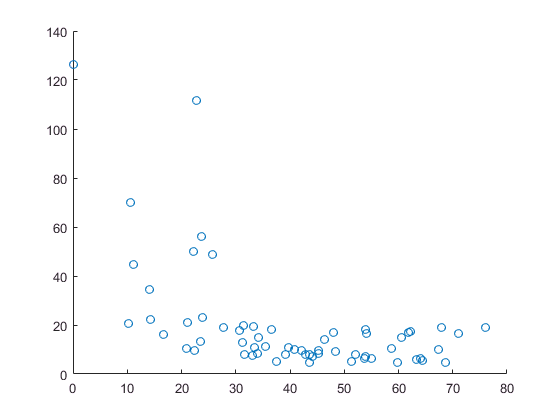


figure
scatter(betaDist(logChans),BigAveResp(logChans))
title('CCEP magnitude response vs. distance from beta channel')

figure
scatter(betaDist(logChans),latencyResp(logChans))
title('CCEP latency vs. distance from beta channel')

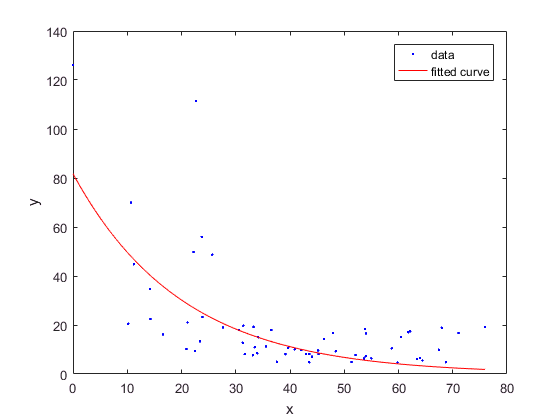


figure
[f,gof] = fit(betaDist',BigAveResp','exp1');
plot(f,betaDist(logChans),BigAveResp(logChans))

gof

gof =            sse: 2.0562e+04
       rsquare: 0.3490
           dfe: 62
    adjrsquare: 0.3385
          rmse: 18.2113


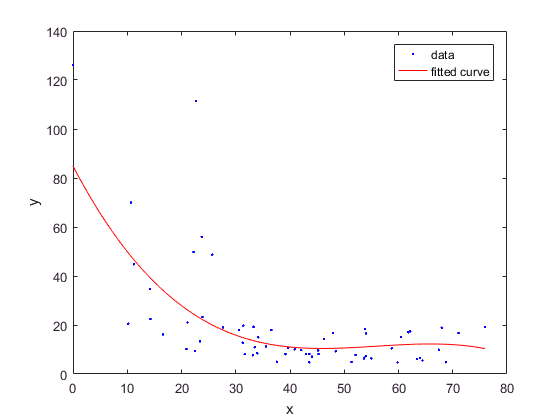


figure
[f,gof] = fit(betaDist',BigAveResp','poly3');
plot(f,betaDist(logChans),BigAveResp(logChans))

gof

gof =            sse: 1.9651e+04
       rsquare: 0.3778
           dfe: 60
    adjrsquare: 0.3467
          rmse: 18.0973
